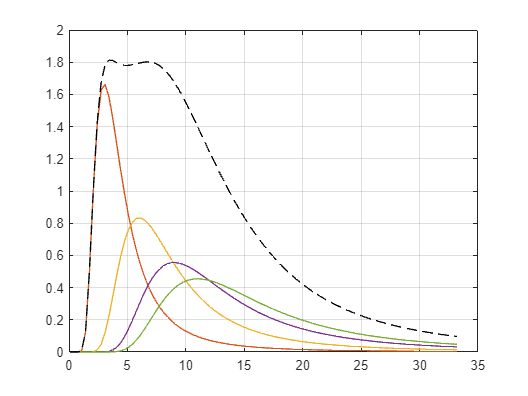

close all;
L_0=5*10^-9;
E_g=1.43;
me_eff=0.067;
mh_eff=0.45;
m_0=9.1093837*10^(-31);
hbar=1.0545718*10^(-34);
mu=1/(1/(m_0*me_eff)+1/(m_0*mh_eff));
q=1.60217663*10^-19;
photon_energy=linspace(1.45,10);
x=photon_energy-E_g;
eta=sqrt((2*mu*L_0^2*x*q)/(pi^2*hbar^2));
Reduced_energy=eta.^2;
xeta=0.2;
A=3;
n_1=sqrt(A);
relative_absorption_0=(1/(xeta*n_1.^2)).*exp((-(n_1./eta-1).^2)./(2*xeta^2));
A=6;
n_2=sqrt(A);
relative_absorption_1=(1/(xeta*n_2.^2)).*exp((-(n_2./eta-1).^2)./(2*xeta^2));
A=9;
n_3=sqrt(A);
relative_absorption_2=(1/(xeta*n_3.^2)).*exp((-(n_3./eta-1).^2)./(2*xeta^2));
A=11;
n_4=sqrt(A);
relative_absorption_3=(1/(xeta*n_4.^2)).*exp((-(n_4./eta-1).^2)./(2*xeta^2));
superposition = relative_absorption_3+relative_absorption_2+relative_absorption_1+relative_absorption_0;
plot(Reduced_energy,relative_absorption_0)
hold on
grid on
plot(Reduced_energy,relative_absorption_0)
plot(Reduced_energy,relative_absorption_1)
plot(Reduced_energy,relative_absorption_2)
plot(Reduced_energy,relative_absorption_3)
plot(Reduced_energy, superposition,"--", Color="k")
hold off

[maxValue,maxIndex]=max(relative_absorption_0);
maxValue=Reduced_energy(maxIndex);
disp(['maximum relative absorption_0 : ',num2str(maxValue)]);

maximum relative absorption_0 : 3.0912


disp(['corresponding Reduced_energy : ',num2str(maxValue)]);

corresponding Reduced_energy : 3.0912
